currentFolder = pwd;
splitted_str = strsplit(currentFolder,'\');
index = contains(splitted_str,'CableSSB-zh');
if ~any(index)
    error('请进入一个在''CableSSB-zh''内的文件夹')
end
mainpath = '';
for i=1:length(splitted_str)
    if index(i)
        path = join(splitted_str(1:i),'\');
        break
    else
        continue
    end
end
MainPath = genpath(path{1});
addpath(MainPath)

clear all
clc

# 建立斜拉悬索协作体系桥梁模型outputCable

original_bridge = CableStayedSuspension_Bridge;
original_bridge.SelfAnchored = false;
original_bridge.build;

Is building a Cable-Stayed Suspension Bridge...


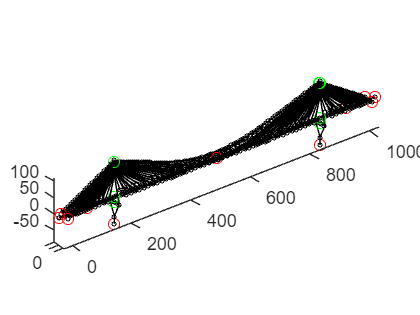

ans =   Figure (1) - 属性:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [440 338 560 420]
       Units: 'pixels'

  显示 所有属性


original_bridge.plot

output_method = OutputToAnsys(original_bridge,"JobName",'OrginalModel',...
    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
    'WorkPath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\CS_Bridge',...
    'MacFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\CS_Bridge\main.mac',...
    'ResultFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\CS_Bridge\result.out');
original_bridge.OutputMethod = output_method;
original_bridge.output

# 建立无索模型，并优化其最小弯曲应变能

% 建立无索模型（用于优化弯曲应变能，不可以直接使用ANSYS运行）
nocable_bridge = NoCable_Bridge(original_bridge);
nocable_bridge.build

Is building a Brigde without Cable System...


output_method = OutputToAnsys(nocable_bridge,"JobName",'NonCableModel',...
    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
    'WorkPath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\NC_Bridge',...
    'MacFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\NC_Bridge\main.mac',...
    'ResultFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\NC_Bridge\result.out');
nocable_bridge.OutputMethod = output_method;
[FEModel,isEquationCompleted] = nocable_bridge.getFiniteElementModel;

Is getting Finite Element Model from ANSYS...


# 刚性支撑连续梁法，获取优化初值

RSC_bridge = RigidSupportedContinuousBeam(original_bridge);
RSC_bridge.build
output_method = OutputToAnsys(nocable_bridge,"JobName",'RSCBridge',...
    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
    'WorkPath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\RSC_Bridge',...
    'MacFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\RSC_Bridge\main.mac',...
    'ResultFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\Rsc_Bridge\result.out');
RSC_bridge.OutputMethod = output_method;
Pz_0 = RSC_bridge.getSupportedForce()'
X_Pz = RSC_bridge.XCoordOfPz;
bar(X_Pz,Pz_0)

% 优化弯曲应变能
Map_Init_Pz = containers.Map(0,Pz_0/2);
nocable_bridge.optimBendingStrainEnergy('MaxIter',50,'DiffMinChange',1e4,'Iter',0,'Map_Iter_Pz',Map_Init_Pz);

nocable_bridge.optimBendingStrainEnergy('MaxIter',30,'DiffMinChange',1e4);

Is optimizing the Bending Strain Energy...
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      40    1.427470e+08    0.000e+00    4.069e+01
    1      80    1.427327e+08    0.000e+00    4.069e+01    1.196e+02
    2     120    1.426612e+08    0.000e+00    4.068e+01    5.982e+02
    3     160    1.423039e+08    0.000e+00    4.062e+01    2.990e+03
    4     200    1.405272e+08    0.000e+00    4.035e+01    1.493e+04
    5     240    1.318865e+08    0.000e+00    3.898e+01    7.414e+04
    6     280    9.441829e+07    0.000e+00    3.239e+01    3.580e+05
    7     320    1.423684e+07    0.000e+00    5.092e+00    1.482e+06
    8     360    1.261567e+07    0.000e+00    4.200e+00    2.434e+05
    9     400    1.261549e+07    0.000e+00    4.200e+00    2.055e+01
   10     440    1.261456e+07    0.000e+00    4.200e+00    6.850e+01
   11     480    1.260994e+07    0.000e+00    4.199e+00    3.425e+02
   1

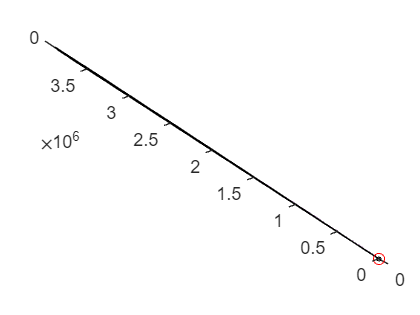

% 结果呈现
Map_Pz = nocable_bridge.Result_Iteration.Map_Iter_Pz;
max_iter = nocable_bridge.Iter_Optimization;
Pz_final = Map_Pz(max_iter);
X_Pz = nocable_bridge.OriginalBridge.getSortedGirderPointXCoord([nocable_bridge.OriginalBridge.findStructureByClass('Hanger'),nocable_bridge.OriginalBridge.findStructureByClass('StayedCable')]);
bar(X_Pz,Pz_final)

Y_final = nocable_bridge.solveCableShape(Pz_final);

ans = 78

X_Pz = nocable_bridge.XCoordOfPz;
for i=1:length(nocable_bridge.ReplacedStayedCable)
    stayed_cable = nocable_bridge.ReplacedStayedCable(i);
    Point_Bottom = stayed_cable.findGirderPoint();
    X_Bottom = [Point_Bottom.X];
    P_girder_z = zeros(1,length(X_Bottom));
    for j=1:length(X_Pz)
        index = abs(X_Pz(j)-X_Bottom) < 1e-5;
        P_girder_z(index) = Pz_final(j);
    end
    stayed_cable.getP(P_girder_z);
end
original_bridge.output